# Del 3 - Tvungne svingninger

Formel for udæmpet tvungen vibration - dvs c = 0 (dæmpningskoefficienten)


$$\ddot x  + \frac{k}{m}x = \frac{F_0 sin(\omega t)}{m}\\

\ddot x  + \omega_n^2 x = \frac{F_0 sin(\omega t)}{m}\\
$$
    

# Formel for dæmpet tvungen vibration


$$\ddot x + \frac{c}{m} \dot x + \frac{k}{m}x = \frac{F_0 sin(\omega t)}{m}$$
 

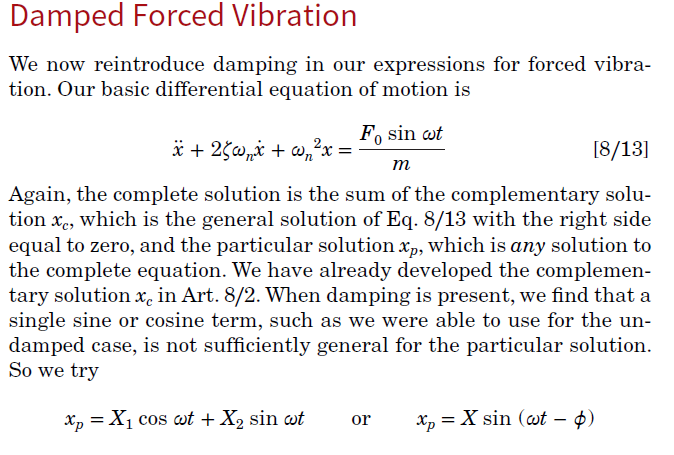

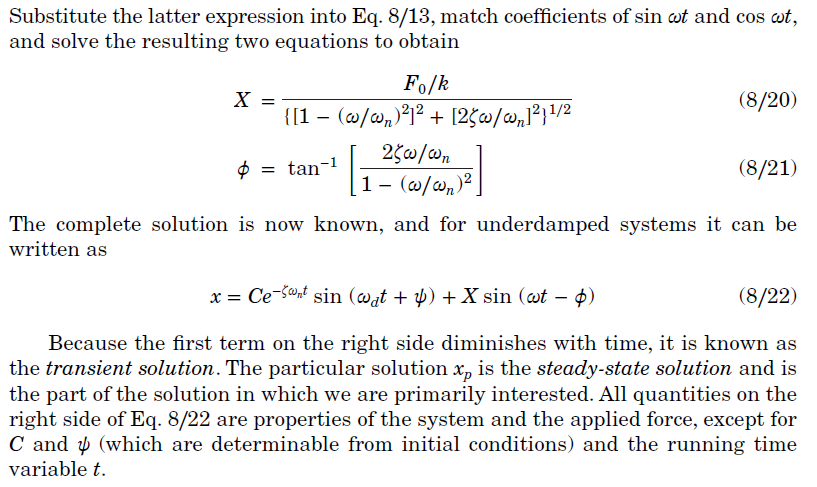

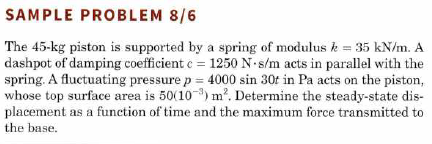

clear
clc
u = symunit;

syms t
k = 35000;   
c = 1250; 
A = 50*10^-3; 
m = 45;
w = 30; 
p0 = 4000;  
p = p0*sin(w*t);
F = p0*A;

wn = sqrt(k/m);


zeta = c/(2*m*wn);

omega_r = w/wn;



X = (F/k)/(sqrt(((1-(omega_r)^2)^2 + (2*zeta.*omega_r).^2)));

phi = atan((2*zeta*omega_r)/(1 - omega_r^2)) + pi;

% de 2 løsninger

t = linspace(0,0.2, 100);

x1 = k*X;
x2 = c*X*w;
x3 = sqrt(x1.^2 + x2.^2);


X1 = k*X*sin(w.*t - phi);
X2 = c*X*w*cos(w.*t - phi);

X3 = X1 + X2;

figure, grid
hold on
plot(t, X1)
plot(t, X2)
plot(t, X3)

% Differencen kommer fra n i linspace
[Maks, I] = max(X3)
Maks2 = sqrt(x1.^2 + x2.^2);

xline(t(I)), yline(X3(I))

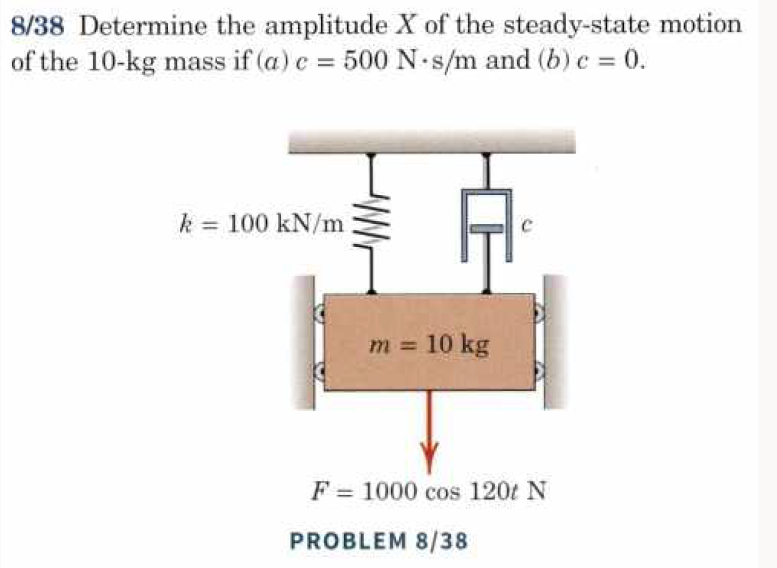

clear
k = 100000;   c = [500, 0];  m = 10; g = 9.81;
w = 120; 
F = 1000;

wn = sqrt(k/m);


zeta = c/(2*m*wn);

omega_r = w/wn;



X = (F/k)./(sqrt(((1-(omega_r)^2)^2 + (2*zeta.*omega_r).^2)));
vpa(X, 3)

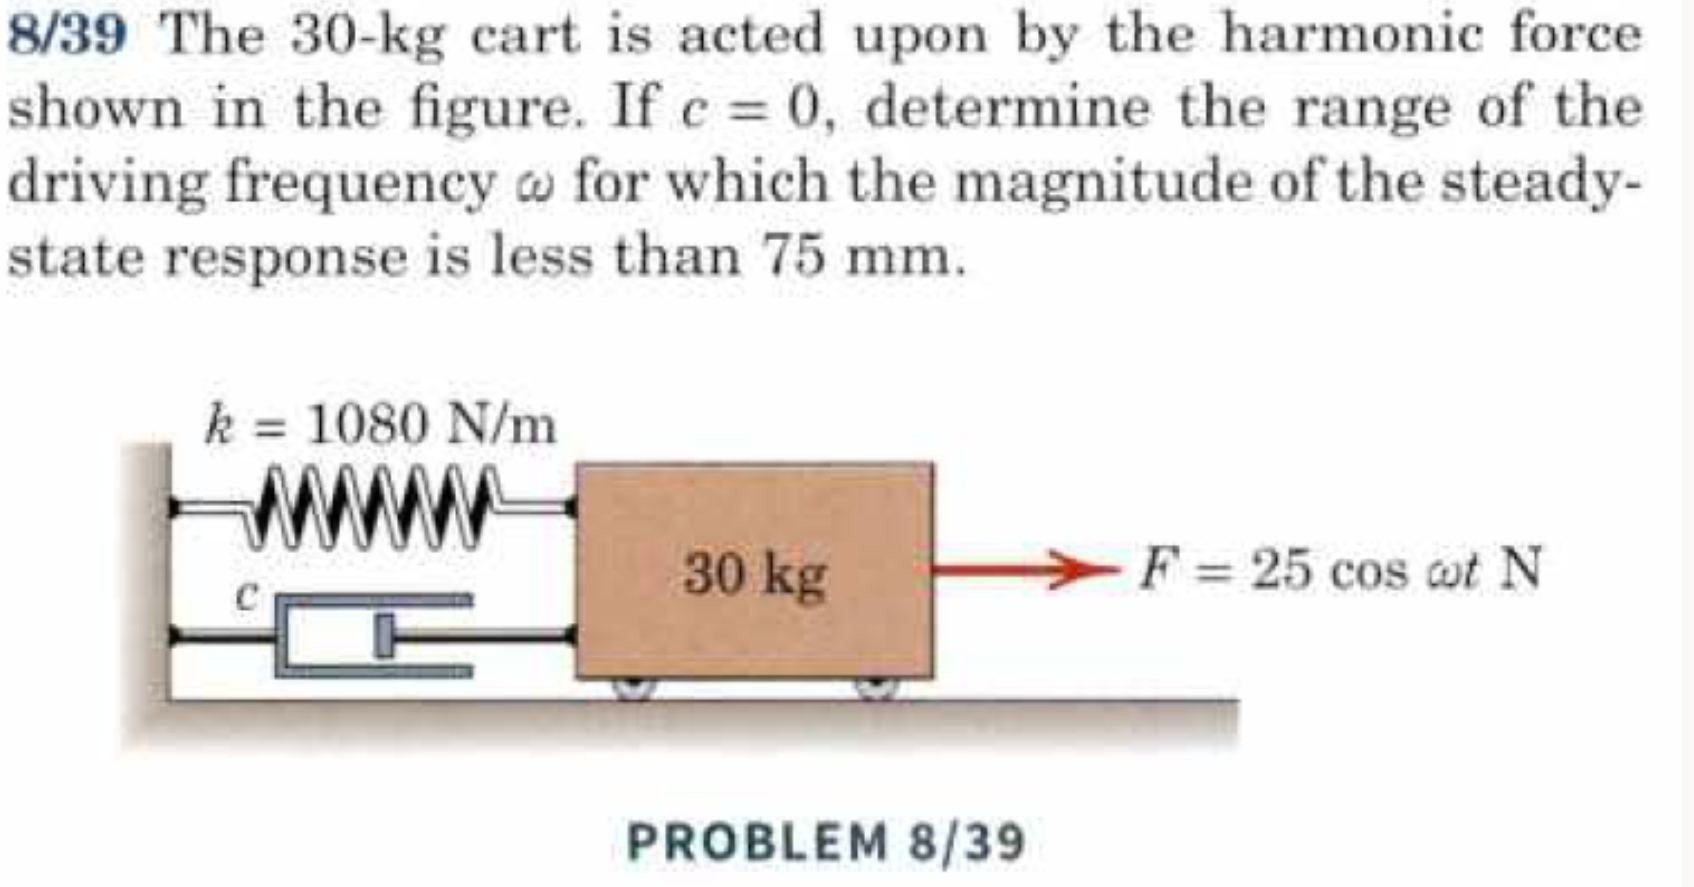

clear
k = 1080;   c = 0;  m = 30; g = 9.81;
syms omega
w = omega; 
F = 25;

wn = sqrt(k/m);

zeta = c/(2*m*wn);

omega_r = w/wn;

X = (F/k)./(sqrt(((1-omega_r^2)^2 + (2*zeta.*omega_r).^2))) == 0.075;

sol = solve(X, w);
vpa(sol, 3)


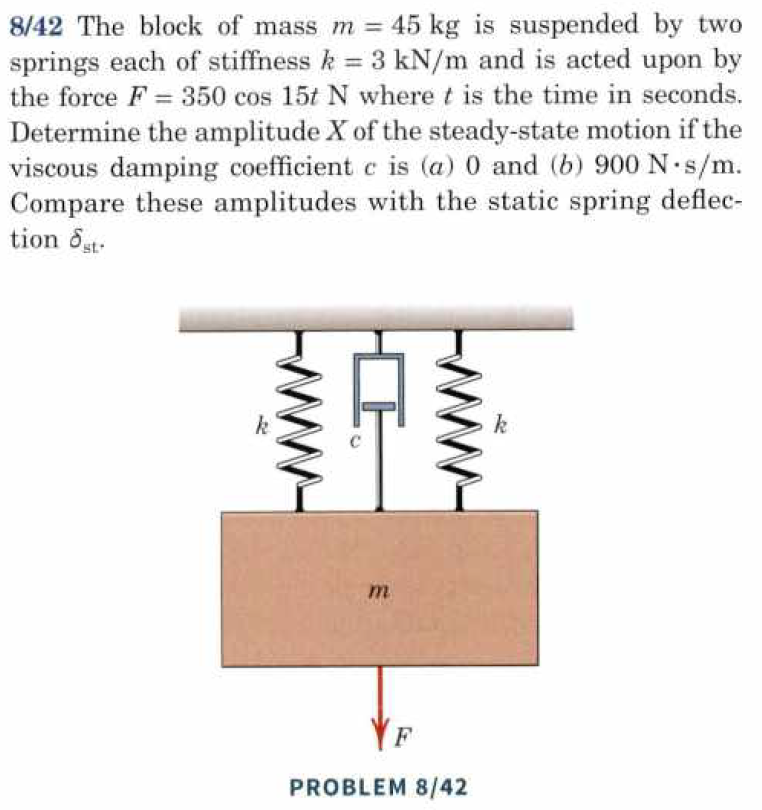

clear 

k = 2*3000;   c = [0 900];  m = 45; g = 9.81;
w = 15; 
F = 350;

wn = sqrt(k/m)

zeta = c/(2*m*wn)

omega_r = w/wn;

X = (F/k)./(sqrt(((1-omega_r^2)^2 + (2*zeta.*omega_r).^2)));
vpa(X,3)

dst = m*g/k

# Bare nogle plots over magnification og faseforskydning

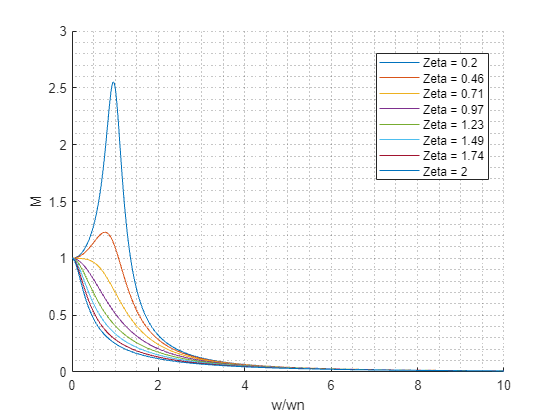

clear
clc

F0 = 10000;
k = 200;
zeta = linspace(0.2,2,8);


for l = 1:length(zeta)
    names(l) = "Zeta = " + round(zeta(l),2);
end


omega_ratio=linspace(0,10,1000);


figure, hold on

grid("minor"), ylabel("M"), xlabel("w/wn")

for i = 1:length(zeta)
    M = 1./(sqrt(((1-(omega_ratio).^2).^2 + (2*zeta(i).*omega_ratio).^2)));
    plot(omega_ratio, M, "DisplayName",names(i))
end

legend('show','location','best')
 
hold off

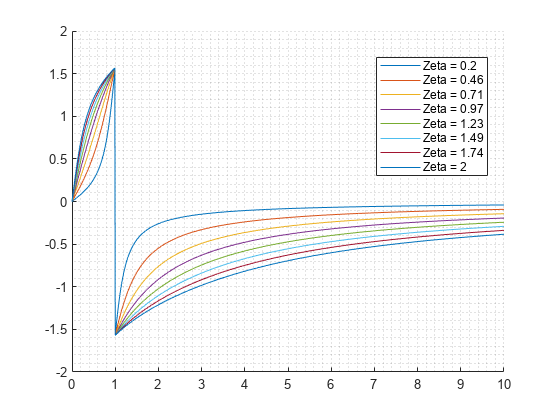



figure, hold on
grid("minor"), %xline(0), yline(0)
for j = 1:length(zeta)
    phi = atan((2*zeta(j).*omega_ratio)./(1-(omega_ratio).^2));

    plot(omega_ratio,phi, "DisplayName",names(j))
end
legend('show','location','best')
hold off